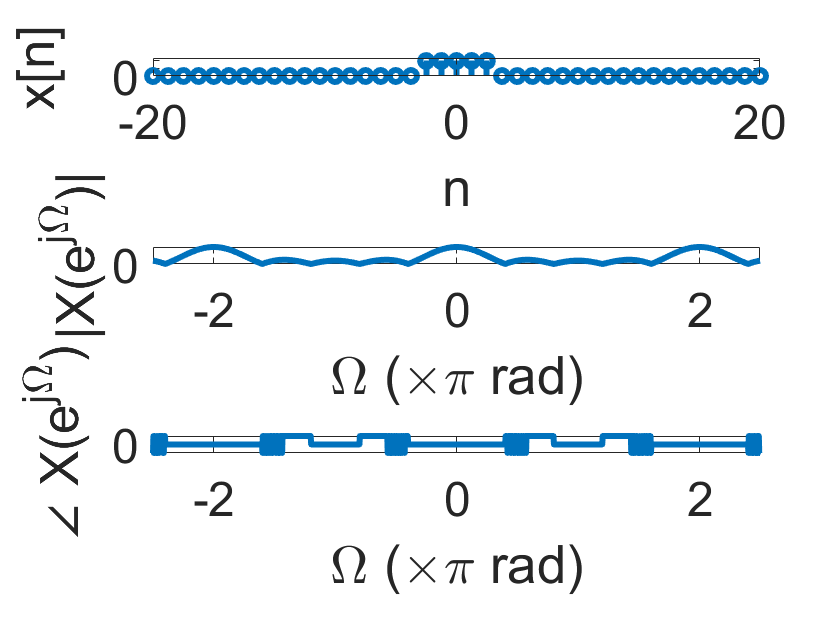

% Plotting the spectrum of a discrete-time rectangular pulse
n=-20:20;
w=-2.5*pi:.01:2.5*pi;
x1=zeros(size(n));
x1(19:23)=1;
X=dtft(n,x1,w);
subplot(3,1,1)
stem(n,x1,'linewidth',3);
set(gca,'fontsize',24)
axis([-20 20 0 1.2])
xlabel('n')
ylabel('x[n]')
subplot(3,1,2)
plot(w/pi,abs(X),'linewidth',3);
set(gca,'fontsize',24)
xlabel('\Omega (\times\pi rad)')
ylabel('|X(e^{j\Omega})|')
subplot(3,1,3)
plot(w/pi,angle(X),'linewidth',3);
set(gca,'fontsize',24)
xlabel('\Omega (\times\pi rad)')
ylabel('\angle X(e^{j\Omega})')